# Run to failure experiment D1 - No twin

In this work remaining useful life (RUL) refers to the total flight time possible for a single mission. Hypothesis here is that the true system should never fail now. But I see that true system will select an explored trajectory if the digital twin passes it, this might be risky, we need to consider dynamic risk. This is in contract to some of our previous work where RUL referred to the entire life of the UAV across multiple missions. This time the digital twin is simulated multiple times for a distribution. 4th simulation in this track, the true system is not allowed to explore trajectories now, and micro updates are made to the rul when some (not all) digital twin missions do not result in success.

#### Simulation Steps

The first step is to load the models, provide an initial RUL estimate (using manufacturers information on the battery is a good starting place), and load some workspace variables. 1D polynomial fitting is used to approximate the degradation rate, and thereby predict the mean of the future degradation value distribution. These predicted values are then passed to a digital twin, which is simulated multiple times to generate a monte carlo distribution of variables tracked such as ending state of charge and voltage and mission outcome. The RUL is updated based on the result of the digital twin simulation, and then the new RUL is used by the real system for trajectory selection. The steps are as follows:

#### Uncertainty Quantification

#### Trajectories

## load main workspace 

% load the workspace necessities
addpath(genpath(pwd));
load_db_params;

% load UAV airframe
uav_sern = 'X001';
conn = database(datasource_name, user_name, password);
octomodel = get_airframe(conn, uav_sern);

% load battery
battery_sern = 'B001';
battery = get_battery(conn, battery_sern);

% load motors
[Motor1, Motor2, Motor3, Motor4, Motor5, Motor6, Motor7, Motor8] = get_motors(conn, octomodel.id);

% close the connection after loading the components, other fuctions handle data writing 
conn.close();

% initial rul estimate (mission flight time) used as baseline in 
rul_hat = 9.0;

% minimum rul
rul_threshold = 5.0;

% load base directory
load_base_workspace;


## Initialize some variables

end_sim_count = 0;

% number of stochastic simulations per mission index
n_samples = 6;

% for poly fitting this is the window size
lookback = 6;
horizon = 2;


% number of missions (can be oversized)
n_missions = 8;

% keep track of delta over time
% number of samples, 3 degradation parameters, 2 coefficients to save
% (slope & intercept)
polys = zeros(n_samples, 3, 2);

q_poly_dist = zeros(n_missions, 4);
r_poly_dist = zeros(n_missions, 4);
m_poly_dist = zeros(n_missions, 4);

% keep track of degradation parameter values for poly fitting
q_deg = zeros(n_samples, 1);
r_deg = zeros(n_samples, 1);
m_deg = zeros(n_samples, 1);

q_deg_dist = zeros(n_missions, 2);
r_deg_dist = zeros(n_missions, 2);
m_deg_dist = zeros(n_missions, 2);

% keep track of rul
ruls = zeros(n_missions, 1);

% keep track of system performance parameters from stochastic runs
avg_pos_errs = zeros(n_samples, 1);
std_pos_errs = zeros(n_samples, 1); 
avg_ctrl_errs = zeros(n_samples, 1);
std_ctrl_errs = zeros(n_samples, 1);
z_ends = zeros(n_samples, 1);
v_ends = zeros(n_samples, 1);
flight_times = zeros(n_samples, 1);

% keep track of stop codes from stochastic runs
stop_codes = zeros(n_samples, 3);

% mean & standard deviation from mission index to mission index
avg_pos_err_dist = zeros(n_missions, 2);
std_pos_err_dist = zeros(n_missions, 2);
avg_ctrl_errs_dist = zeros(n_missions, 2);
std_ctrl_errs_dist = zeros(n_missions, 2);
z_ends_dist = zeros(n_missions, 2);
v_ends_dist = zeros(n_missions, 2);
flight_times_dist = zeros(n_missions, 2);
stop_codes_dist = zeros(n_missions, 3);


## Main Loop

for mission_idx = 1:n_missions
    tic

####         the lookback and horizon window sizes are a function of the number of missions

    % by increasing the window size over time we are accounting for more data
    % and the variance in the degradation rate estimations will decrease naturally
    if mission_idx >= 12 && mission_idx < 20
        lookback = 8;
        horizon = 2;
    elseif mission_idx >= 20 && mission_idx < 30
        lookback = 10;
        horizon = 3;
    elseif mission_idx >= 30 && mission_idx < 50
        lookback = 12;
        horizon = 3;
    elseif mission_idx >= 50 
        lookback = 9;
        horizon = 2;
    end
    
    % keep track of the current rul (maximum mission flight time) estimate
    ruls(mission_idx) = rul_hat;    

##         Stochastic simulation

            each sample selects a random trajectory (there are now 36 trajectories to choose from)

    for sample_num = 1:n_samples
       load_trajectory;
        while trajectory.path_time > rul_hat
            load_trajectory;
        end
        fprintf("[INFO] mission number: %d, sample number: %d, trajectory id <%d> with path_time: %.2f that meets constraint: path_time < %.2f",mission_idx, sample_num, trajectory.id, trajectory.path_time, rul_hat)
        
        sys = "TrueSystem";
        octomodel.sampletime = true_sample_rate;
        fprintf('[INFO] simulating true system on i: %d\n', mission_idx)
        %tic
        sim('truesystem.slx');
        %toc

####                   Capture system performance parameters

        avg_pos_errs(sample_num) = mean(euclidean_pos_err.Data(:,1));        
        std_pos_errs(sample_num) = std(euclidean_pos_err.Data(:,1));
        avg_ctrl_errs(sample_num) = mean([ctrl_err.Data(:,1); ctrl_err.Data(:,2)]);
        std_ctrl_errs(sample_num) = std([ctrl_err.Data(:,1); ctrl_err.Data(:,2)]);
        z_ends(sample_num) = battery_actual.Data(end, 2);
        v_ends(sample_num) = battery_actual.Data(end, 1);
        flight_times(sample_num) = round(flight_time.Data(end),4);    
        stop_codes(sample_num, :) = any(stop_code.Data(:,:));

###                 update degradation variance

                    use the kalman filter estimates

        r_var = battery_observed.Data(end, 6);
        q_var = battery_observed.Data(end, 8);
        m_var = motors.Data(2, 4);

#### **                  keep track of the degradation parameters for each sample**

        r_deg(sample_num, 1) = battery.R0;
        q_deg(sample_num, 1) = battery.Q;
        m_deg(sample_num, 1) = Motor2.Req;

###                 Update degradation rate of change

        if mission_idx > lookback
            x = double(((mission_idx - (lookback)):1:mission_idx-1)');
            r_ = r_deg_dist(x,2).*randn(lookback,1)+r_deg_dist(x,1);
            r_poly = polyfit(x, smoothdata(r_, 'rlowess', 5), 1);
            
            q_ = q_deg_dist(x,2).*randn(lookback,1)+q_deg_dist(x,1);
            q_poly = polyfit(x, smoothdata(q_, 'rlowess', 5), 1);
            
            m_ = m_deg_dist(x,2).*randn(lookback,1)+m_deg_dist(x,1);
            m_poly = polyfit(x, smoothdata(m_, 'rlowess', 5), 1);

            polys(sample_num, 1, :) = r_poly;
            polys(sample_num, 2, :) = q_poly;
            polys(sample_num, 3, :) = m_poly;
            
            r_mu = polyval(r_poly, mission_idx + horizon);
            q_mu = polyval(q_poly, mission_idx + horizon);
            m_mu = polyval(m_poly, mission_idx + horizon);
        end
        %%%write_degradation_data;
        %%%clear('trajectory', 'battery_actual', 'battery_observed', 'ctrl_err', 'current', 'current_rs', 'euclidean_pos_err', 'flight_time', 'motors', 'pos_observed', 'pos_actual', 'stop_code' );    

### **                sample the degradation parameters and update**

        if mission_idx > lookback
            battery.R0 = max(abs(normrnd(r_mu, r_var)), .0001);
            battery.Q = min(abs(normrnd(q_mu, q_var)), 15.5);
            Motor2.Req = max(abs(normrnd(m_mu, m_var)), .001);  
        else
            battery.R0 = max(abs(normrnd(rdeg(mission_idx), r_var)), .0001);
            battery.Q = min(abs(normrnd(qdeg(mission_idx), q_var)), 15.5);
            Motor2.Req = max(abs(normrnd(mdeg(mission_idx), m_var)), .001);  
        end
        fprintf("[INFO] degradation parameters: %.4f\t%.4f\t%.4f", battery.R0, battery.Q, Motor2.Req)
    end
    toc

###                          end of stochastic simulation for the current mission index     

###          Update component degradation forecast distributions

    r_deg_dist(mission_idx, :) = [mean(r_deg), std(r_deg)];
    q_deg_dist(mission_idx, :) = [mean(q_deg), std(q_deg)];
    m_deg_dist(mission_idx, :) = [mean(m_deg), std(m_deg)]; 

###          Update degradation rate distributions 

            average delta (rate of change)  (rqm_poly_means(1)) of the samples and standard deviation  (rqm_poly_stds(2))

            average bias (rqm_poly_means(2)) of the samples and standard deviation of the bais  (rqm_poly_stds(2))

    r_poly_means = reshape(mean(polys(:, 1, :)), 1, []);
    r_poly_stds = reshape(std(polys(:,1,:)), 1, []);
    r_poly_dist(mission_idx, :) = [r_poly_means(1) r_poly_stds(1) r_poly_means(2) r_poly_stds(2)];
    
    q_poly_means = reshape(mean(polys(:, 2, :)), 1, []);
    q_poly_stds = reshape(std(polys(:,2,:)), 1, []);
    q_poly_dist(mission_idx, :) = [q_poly_means(1) q_poly_stds(1) q_poly_means(2) q_poly_stds(2)];
    
    m_poly_means = reshape(mean(polys(:, 3, :)), 1, []);
    m_poly_stds = reshape(std(polys(:,3,:)), 1, []);
    m_poly_dist(mission_idx, :) = [m_poly_means(1) m_poly_stds(1) m_poly_means(2) m_poly_stds(2)];  

###          Update system performance parameters

    avg_pos_err_dist(mission_idx, :) = [mean(avg_pos_errs), std(avg_pos_errs)];
    std_pos_err_dist(mission_idx, :) = [mean(std_pos_errs), std(std_pos_errs)];
    avg_ctrl_err_dist(mission_idx, :) = [mean(avg_ctrl_errs), std(avg_ctrl_errs)];
    std_ctrl_err_dist(mission_idx, :) = [mean(std_ctrl_errs), std(std_ctrl_errs)];
    z_ends_dist(mission_idx, :) = [mean(z_ends), std(z_ends)];
    v_ends_dist(mission_idx, :) = [mean(v_ends), std(v_ends)];
    flight_times_dist(mission_idx, :) = [mean(flight_times), std(flight_times)];
    stop_codes_dist(mission_idx, :) = [sum(stop_codes(:, 1))/n_samples, sum(stop_codes(:, 2))/n_samples, sum(stop_codes(:, 3))/n_samples];

###          Write stochastic data to system_parameter_tb

    write_stochastic_data;

###           write mission data to database

            TODO - move mission_id section to front, only call db once for this, then increment

    distance = calculatedistance([pos_actual.Data(:,1) pos_actual.Data(:,2)]);
    conn = database(datasource_name, user_name, password);
    mission_id = 99999; 
    %%%mission_id = table2array(select(conn, 'select id from mission_tb mt order by id desc limit 1;'));
    if isempty(mission_id)
        mission_id = 1;
    else
        mission_id = mission_id + 1;
    end
    start = table2array(select(conn, 'select mt.dt_stop from mission_tb mt order by dt_stop desc limit 1;'));
    conn.close();
    if isempty(start)
        start = datetime(now, 'ConvertFrom', 'datenum');
    end
    start = datetime(start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
    start = dateshift(start, 'start', 'second');
    start = start + hours(1);
    stop = start + seconds(flight_time.Data(end, 1)*60);
    
    fprintf("[INFO] i: %d\tmission_id: %d\trul_hat: %.2f\tflight_time: %.2f\tdistance: %.2f\tR0: %.5f\tQ: %.2f\tReq: %.5f", mission_idx, mission_id, rul_hat, flight_time.Data(end, 1), distance, battery.R0, battery.Q, Motor2.Req)
    
    %%%write_mission_data;
    %%%write_battery_data;
    %%%write_flight_data;  

###         Update the RUL

           NOTE - This is the function that we are trying to learn! In this application, RUL is a function of position error variance, ending state of charge, and flight time,

            yet we do not know how these interact with each other. 

    % increase rul estimate by 20 seconds if 100% of the samples result in
    % success
    if stop_codes_dist(mission_idx, 3) > .99
        rul_hat = rul_hat + .33;
    % if 95% or greater result in success, then just update it with a small
    % "cost of living" amount
    elseif stop_codes_dist(mission_idx, 3) > .95
        rul_hat = rul_hat - .02;
    % decrease the rul estimate by 10 seconds if 90%-95% are success
    elseif stop_codes_dist(mission_idx, 3) > .90
        rul_hat = rul_hat - .17;
    % decrease the rul estimate by 20 seconds if 85%-90% are success
    elseif stop_codes_dist(mission_idx, 3) > .85
        rul_hat = rul_hat - .33;   
    % decrease the rul estimate by 40 seconds if less than 85% of the
    % samples result in success
    else
        rul_hat = rul_hat - .66;   
    end
    
    % update the end simulation count to know when to stop
    if stop_codes_dist(mission_idx, 3) < .50
        end_sim_count = end_sim_count + 1;
        if end_sim_count == 10
            break;
        end
    end
    
end

[INFO] mission number: 1, sample number: 1, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0002	15.5000	0.2361

[INFO] mission number: 1, sample number: 2, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0002	15.3553	0.2324

[INFO] mission number: 1, sample number: 3, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0032	15.5000	0.2365

[INFO] mission number: 1, sample number: 4, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0034	14.8644	0.2359

[INFO] mission number: 1, sample number: 5, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0013	14.3948	0.2355

[INFO] mission number: 1, sample number: 6, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.00

[INFO] simulating true system on i: 1


[INFO] degradation parameters: 0.0027	15.5000	0.2391

Elapsed time is 633.910852 seconds.


[INFO] i: 1	mission_id: 100000	rul_hat: 9.00	flight_time: 8.43	distance: 616.20	R0: 0.00268	Q: 15.50	Req: 0.23915

[INFO] mission number: 2, sample number: 1, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0011	15.3061	0.2365

[INFO] mission number: 2, sample number: 2, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0002	14.6761	0.2379

[INFO] mission number: 2, sample number: 3, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0042	15.5000	0.2369

[INFO] mission number: 2, sample number: 4, trajectory id <34> with path_time: 7.27 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0026	14.6951	0.2355

[INFO] mission number: 2, sample number: 5, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0087	14.9778	0.2336

[INFO] mission number: 2, sample number: 6, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.33

[INFO] simulating true system on i: 2


[INFO] degradation parameters: 0.0029	14.8346	0.2378

Elapsed time is 628.009992 seconds.


[INFO] i: 2	mission_id: 100000	rul_hat: 9.33	flight_time: 8.43	distance: 616.22	R0: 0.00288	Q: 14.83	Req: 0.23778

[INFO] mission number: 3, sample number: 1, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0040	14.6309	0.2371

[INFO] mission number: 3, sample number: 2, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0002	15.0980	0.2423

[INFO] mission number: 3, sample number: 3, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0011	14.7508	0.2349

[INFO] mission number: 3, sample number: 4, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0025	15.5000	0.2377

[INFO] mission number: 3, sample number: 5, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0033	14.2092	0.2351

[INFO] mission number: 3, sample number: 6, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.66

[INFO] simulating true system on i: 3


[INFO] degradation parameters: 0.0022	13.2179	0.2398

Elapsed time is 694.159517 seconds.


[INFO] i: 3	mission_id: 100000	rul_hat: 9.66	flight_time: 9.46	distance: 689.29	R0: 0.00218	Q: 13.22	Req: 0.23977

[INFO] mission number: 4, sample number: 1, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0003	15.5000	0.2434

[INFO] mission number: 4, sample number: 2, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0011	15.1621	0.2381

[INFO] mission number: 4, sample number: 3, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0022	14.4857	0.2382

[INFO] mission number: 4, sample number: 4, trajectory id <32> with path_time: 7.77 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0008	14.7113	0.2403

[INFO] mission number: 4, sample number: 5, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0009	14.8684	0.2379

[INFO] mission number: 4, sample number: 6, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 9.99

[INFO] simulating true system on i: 4


[INFO] degradation parameters: 0.0086	15.5000	0.2378

Elapsed time is 711.726010 seconds.


[INFO] i: 4	mission_id: 100000	rul_hat: 9.99	flight_time: 9.46	distance: 689.32	R0: 0.00865	Q: 15.50	Req: 0.23781

[INFO] mission number: 5, sample number: 1, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0011	14.4132	0.2409

[INFO] mission number: 5, sample number: 2, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0033	14.6476	0.2408

[INFO] mission number: 5, sample number: 3, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0034	15.1092	0.2374

[INFO] mission number: 5, sample number: 4, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0067	14.8653	0.2384

[INFO] mission number: 5, sample number: 5, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0024	13.0053	0.2385

[INFO] mission number: 5, sample number: 6, trajectory id <36> with path_time: 8.30 that meets constraint: path_time < 10.32

[INFO] simulating true system on i: 5


[INFO] degradation parameters: 0.0059	15.5000	0.2380

Elapsed time is 740.100209 seconds.


[INFO] i: 5	mission_id: 100000	rul_hat: 10.32	flight_time: 8.30	distance: 596.95	R0: 0.00590	Q: 15.50	Req: 0.23798

[INFO] mission number: 6, sample number: 1, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0017	14.5398	0.2366

[INFO] mission number: 6, sample number: 2, trajectory id <33> with path_time: 8.42 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0021	13.7397	0.2407

[INFO] mission number: 6, sample number: 3, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0015	15.3324	0.2396

[INFO] mission number: 6, sample number: 4, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0043	15.5000	0.2384

[INFO] mission number: 6, sample number: 5, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0018	15.1814	0.2380

[INFO] mission number: 6, sample number: 6, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 10.65

[INFO] simulating true system on i: 6


[INFO] degradation parameters: 0.0048	13.7183	0.2351

Elapsed time is 787.812549 seconds.


[INFO] i: 6	mission_id: 100000	rul_hat: 10.65	flight_time: 9.46	distance: 689.34	R0: 0.00476	Q: 13.72	Req: 0.23509

[INFO] mission number: 7, sample number: 1, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


x =      1
     2
     3
     4
     5
     6


[INFO] degradation parameters: 0.0026	15.5000	0.2414

[INFO] mission number: 7, sample number: 2, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


x =      1
     2
     3
     4
     5
     6


[INFO] degradation parameters: 0.0066	14.2301	0.2410

[INFO] mission number: 7, sample number: 3, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


x =      1
     2
     3
     4
     5
     6


[INFO] degradation parameters: 0.0042	14.8156	0.2462

[INFO] mission number: 7, sample number: 4, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


x =      1
     2
     3
     4
     5
     6


[INFO] degradation parameters: 0.0054	14.2183	0.2404

[INFO] mission number: 7, sample number: 5, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


x =      1
     2
     3
     4
     5
     6


[INFO] degradation parameters: 0.0070	15.1540	0.2438

[INFO] mission number: 7, sample number: 6, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 10.98

[INFO] simulating true system on i: 7


x =      1
     2
     3
     4
     5
     6


[INFO] degradation parameters: 0.0126	14.2965	0.2389

Elapsed time is 868.196669 seconds.


[INFO] i: 7	mission_id: 100000	rul_hat: 10.98	flight_time: 10.85	distance: 807.91	R0: 0.01256	Q: 14.30	Req: 0.23889

[INFO] mission number: 8, sample number: 1, trajectory id <31> with path_time: 10.84 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


x =      2
     3
     4
     5
     6
     7


[INFO] degradation parameters: 0.0042	14.5544	0.2480

[INFO] mission number: 8, sample number: 2, trajectory id <35> with path_time: 9.49 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


x =      2
     3
     4
     5
     6
     7


[INFO] degradation parameters: 0.0002	14.7428	0.2464

[INFO] mission number: 8, sample number: 3, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


x =      2
     3
     4
     5
     6
     7


[INFO] degradation parameters: 0.0028	14.9936	0.2406

[INFO] mission number: 8, sample number: 4, trajectory id <21> with path_time: 10.59 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


x =      2
     3
     4
     5
     6
     7


[INFO] degradation parameters: 0.0064	15.5000	0.2450

[INFO] mission number: 8, sample number: 5, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


x =      2
     3
     4
     5
     6
     7


[INFO] degradation parameters: 0.0080	11.3355	0.2436

[INFO] mission number: 8, sample number: 6, trajectory id <26> with path_time: 10.22 that meets constraint: path_time < 11.31

[INFO] simulating true system on i: 8


x =      2
     3
     4
     5
     6
     7


[INFO] degradation parameters: 0.0093	14.2764	0.2486

Elapsed time is 864.452621 seconds.


[INFO] i: 8	mission_id: 100000	rul_hat: 11.31	flight_time: 10.22	distance: 736.58	R0: 0.00928	Q: 14.28	Req: 0.24865

### End of experiment

q_poly_means = reshape(mean(polys(:, 2, :)), 1, []);
q_poly_stds = reshape(std(polys(:,2,:)), 1, []);
q_poly_dist = [q_poly_means(1) q_poly_stds(1) q_poly_means(2) q_poly_stds(2)];



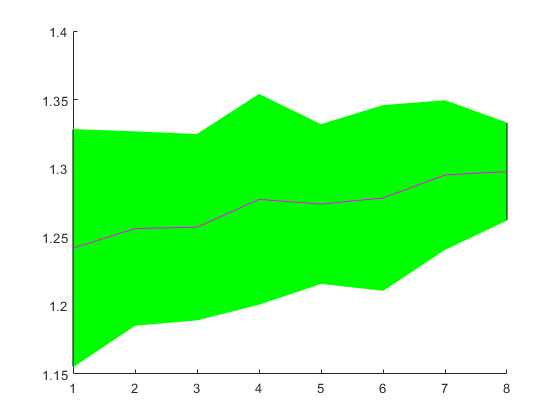

y = avg_pos_err_dist;

x = 1:8;
f1 = figure; clf;
hold on

cb1 = y(:,1)+2*y(:,2);
cb1 = cb1';
cb2 = y(:,1)-2*y(:,2);
cb2 = cb2';

x2 = [x, fliplr(x)];
inbetween = [cb1, fliplr(cb2)];
fill(x2, inbetween, 'g');
plot(x, cb1, 'g')
plot(x, cb2, 'g')
plot(x, y(:,1), 'm')

hold off

# ******************** end of simulation code

flight_times_dist


 if mission_idx > lookback
            x = double(((mission_idx - (lookback)):1:mission_idx-1)');
            r_ = r_deg_dist(x,2).*randn(lookback,1)+r_deg_dist(x,1);
            r_poly = polyfit(x, smoothdata(r_, 'rlowess', 5), 1);
            
            q_ = q_deg_dist(x,2).*randn(lookback,1)+q_deg_dist(x,1);
            q_poly = polyfit(x, smoothdata(q_, 'rlowess', 5), 1);
            
            m_ = m_deg_dist(x,2).*randn(lookback,1)+m_deg_dist(x,1);
            m_poly = polyfit(x, smoothdata(m_, 'rlowess', 5), 1);

            polys(sample_num, 1, :) = r_poly;
            polys(sample_num, 2, :) = q_poly;
            polys(sample_num, 3, :) = m_poly;
            
            r_mu = polyval(r_poly, mission_idx + horizon);
            q_mu = polyval(q_poly, mission_idx + horizon);
            m_mu = polyval(m_poly, mission_idx + horizon);
        end
        %%%write_degradation_data;
        %%%clear('trajectory', 'battery_actual', 'battery_observed', 'ctrl_err', 'current', 'current_rs', 'euclidean_pos_err', 'flight_time', 'motors', 'pos_observed', 'pos_actual', 'stop_code' );    

### **                sample the degradation parameters and update**

        if mission_idx > lookback
            batterytwin.R0 = max(abs(normrnd(r_mu, r_var)), .0001);
            batterytwin.Q = min(abs(normrnd(q_mu, q_var)), 15.5);
            Motortwin2.Req = max(abs(normrnd(m_mu, m_var)), .001);  
        else
            battery.R0 = max(abs(normrnd(rdeg(mission_idx), r_var)), .0001);
            battery.Q = min(abs(normrnd(qdeg(mission_idx), q_var)), 15.5);
            Motor2.Req = max(abs(normrnd(mdeg(mission_idx), m_var)), .001);  
        end

###   Update system performance parameters

    avg_pos_err_dist(mission_idx, :) = [mean(avg_pos_errs), std(avg_pos_errs)];
    std_pos_err_dist(mission_idx, :) = [mean(std_pos_errs), std(std_pos_errs)];
    avg_ctrl_err_dist(mission_idx, :) = [mean(avg_ctrl_errs), std(avg_ctrl_errs)];
    std_ctrl_err_dist(mission_idx, :) = [mean(std_ctrl_errs), std(std_ctrl_errs)];
    z_ends_dist(mission_idx, :) = [mean(z_ends), std(z_ends)];
    v_ends_dist(mission_idx, :) = [mean(v_ends), std(v_ends)];
    flight_times_dist(mission_idx, :) = [mean(flight_times), std(flight_times)];
    stop_codes_dist(mission_idx, :) = [sum(stop_codes(:, 1))/n_samples, sum(stop_codes(:, 2))/n_samples, sum(stop_codes(:, 3))/n_samples];

###           Update degradation rate distributions 

            average delta (rate of change)  (rqm_poly_means(1)) of the samples and standard deviation  (rqm_poly_stds(2))

            average bias (rqm_poly_means(2)) of the samples and standard deviation of the bais  (rqm_poly_stds(2))

    r_poly_means = reshape(mean(polys(:, 1, :)), 1, []);
    r_poly_stds = reshape(std(polys(:,1,:)), 1, []);
    r_poly_dist(mission_idx, :) = [r_poly_means(1) r_poly_stds(1) r_poly_means(2) r_poly_stds(2)];
    
    q_poly_means = reshape(mean(polys(:, 2, :)), 1, []);
    q_poly_stds = reshape(std(polys(:,2,:)), 1, []);
    q_poly_dist(mission_idx, :) = [q_poly_means(1) q_poly_stds(1) q_poly_means(2) q_poly_stds(2)];
    
    m_poly_means = reshape(mean(polys(:, 3, :)), 1, []);
    m_poly_stds = reshape(std(polys(:,3,:)), 1, []);
    m_poly_dist(mission_idx, :) = [m_poly_means(1) m_poly_stds(1) m_poly_means(2) m_poly_stds(2)];  
    

###          Write stochastic data to system_parameter_tb

    write_stochastic_data;

###         Update the RUL

           NOTE - This is the function that we are trying to learn! In this application, RUL is a function of position error variance, ending state of charge, and flight time,

            yet we do not know how these interact with each other. 

    % increase rul estimate by 20 seconds if 100% of the samples result in
    % success
    if stop_codes_dist(mission_idx, 3) > .99
        rul_hat = rul_hat + .33;
    % if 95% or greater result in success, then just update it with a small
    % "cost of living" amount
    elseif stop_codes_dist(mission_idx, 3) > .95
        rul_hat = rul_hat - .02;
    % decrease the rul estimate by 10 seconds if 90%-95% are success
    elseif stop_codes_dist(mission_idx, 3) > .90
        rul_hat = rul_hat - .17;
    % decrease the rul estimate by 20 seconds if 85%-90% are success
    elseif stop_codes_dist(mission_idx, 3) > .85
        rul_hat = rul_hat - .33;   
    % decrease the rul estimate by 40 seconds if less than 85% of the
    % samples result in success
    else
        rul_hat = rul_hat - .66;   
    end
    
    % update the end simulation count to know when to stop
    if stop_codes_dist(mission_idx, 3) < .50
        end_sim_count = end_sim_count + 1;
        if end_sim_count == 10
            disp('10')
        end
    end
